# Tutorial 5 -- Audio

## The MIR Toolbox

### setting the Matlab path

Start by setting a path to the folder containing the MIR Toolbox, which contains all of the functions we'll be using here.

addpath(genpath('D:\Dropbox\files\Jobs\2017_TexasTech\teaching\2021_Fall\VPA5300_DH\inclass\tutorials\tutorial_05_audio\2share\code\mirtoolbox1-7-2'))

### consulting the manual

Let's start by consulting the manual or the primer, both of which make for entertaining reading! (If you get an error message here, just open the pdf files without Matlab's help.)

cd('D:\Dropbox\files\Jobs\2017_TexasTech\teaching\2021_Fall\VPA5300_DH\inclass\tutorials\tutorial_05_audio\2share\tutorial_05_audio\code\mirtoolbox1-7-2\MIRtoolbox1.7.2')
system('manual1.7.2.pdf &');
system('MIRtoolboxPrimer.pdf &');

### asking for help

We can also learn about the MIR Toolbox's many functions from within Matlab itself by using the help function.

help mirtoolbox

  MIRtoolbox
  Version 1.7.2 8-January-2019
 
  A more detailed documentation of each function is available using the
  help command. For instance, type help miraudio.
 
  A complete documentation is available in the downloaded folder and online.
 			http://www.jyu.fi/music/coe/materials/mirtoolbox
 
 BASIC AUDIO OPERATIONS
  miraudio         - Loads and return waveform
  mirframe         - Decomposes into successive frames
  mirsegment       - Decomposes into successive segments
  mirlength        - Temporal length
  mirpeaks         - Peak picking
 
 DATA OUTPUT
  mirgetdata       - Return result as a Matlab standard structure
  mirsave          - Save audio and othe

### mirplay

So many functions to choose from! Let's start by playing an audio file from 'tutorial_05_audio\data'.

cd('D:\Dropbox\files\Jobs\2017_TexasTech\teaching\2021_Fall\VPA5300_DH\inclass\tutorials\tutorial_05_audio\2share\tutorial_05_audio\data')
mirplay('7-3-17, 3_08 AM.m4a')

Computing miraudio related to 7-3-17, 3_08 AM.m4a...
Computing mirsum related to 7-3-17, 3_08 AM.m4a...
Computing mirplay related to 7-3-17, 3_08 AM.m4a...
Playing file: 7-3-17, 3_08 AM.m4a


#### batch listening

mirplay will also let you play every file in a given folder! More on mirplay later...

mirplay('Folder')

*** File # 1/7: Bean Growls.m4a
Computing miraudio related to Bean Growls.m4a...
Computing mirsum related to Bean Growls.m4a...
Computing mirplay related to Bean Growls.m4a...
Playing file: Bean Growls.m4a
Elapsed time is 26.524426 seconds.

*** File # 2/7: Mazeppa.wav
Computing miraudio related to Mazeppa.wav...
Computing mirsum related to Mazeppa.wav...
Computing mirplay related to Mazeppa.wav...
Playing file: Mazeppa.wav


## Import and Visualization

### time-domain representations

#### miraudio

Now let's import an audio file and look at it in the time domain. We'll save it as a variable called 'mus'. (Remember not to suppress the output with the ';' symbol!)

Computing miraudio related to 7-3-17, 3_08 AM.m4a...
Computing mirsum related to 7-3-17, 3_08 AM.m4a...
Elapsed time is 0.584712 seconds.
 
mus is the Audio waveform related to 7-3-17, 3_08 AM.m4a, of sampling rate 48000 Hz.


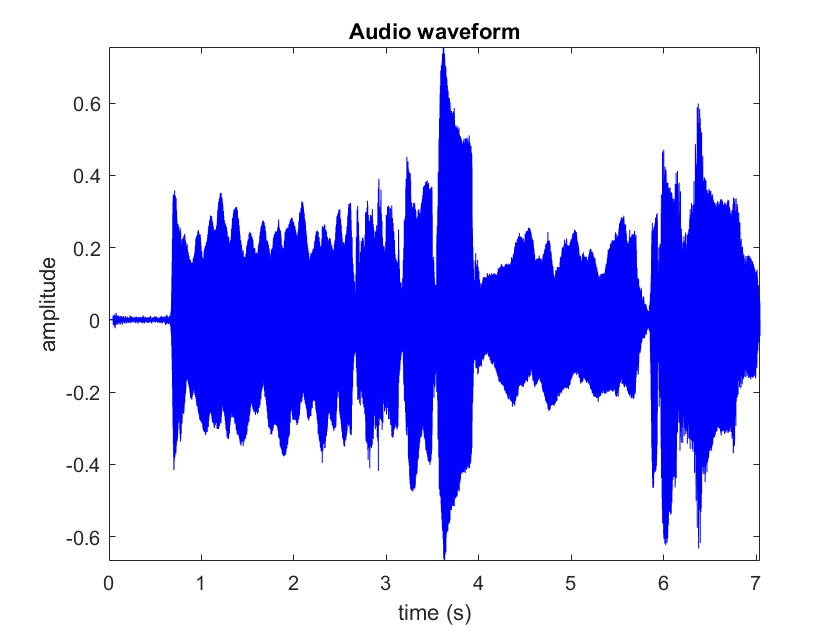

Its content is displayed in Figure 1.
 


mus = miraudio('7-3-17, 3_08 AM.m4a')

#### mirgetdata

We can also produce this figure without the MIR Toolbox's help by extracting the data using the mirgetdata function.

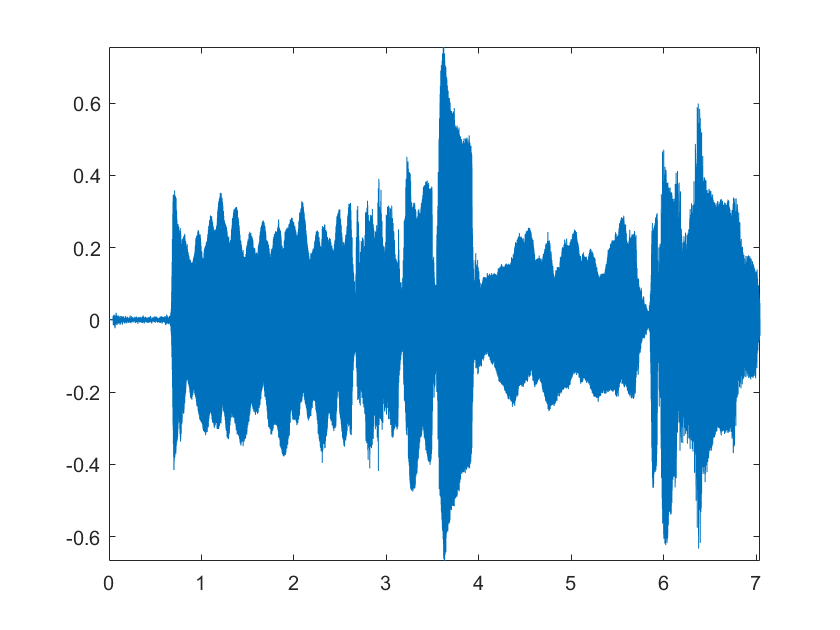

data = mirgetdata(mus);
fs = cell2mat(get(mus,'Sampling'));
figure; plot([1/fs:1/fs:length(data)/fs]',data)
xlim([0 length(data)/fs])
ylim([min(data) max(data)])

#### mirlength

How long is this recording, anyway?

mirlength(mus)

Computing mirlength related to 7-3-17, 3_08 AM.m4a...
 
The Temporal length related to file 7-3-17, 3_08 AM.m4a is 7.04 s.
 


#### batch processing with miraudio

We can also batch process these audio files using miraudio!

examples = miraudio('Folder')

*** File # 1/7: Bean Growls.m4a
Computing miraudio related to Bean Growls.m4a...
Computing mirsum related to Bean Growls.m4a...
Elapsed time is 0.733080 seconds.

*** File # 2/7: Mazeppa.wav
Computing miraudio related to Mazeppa.wav...
Computing mirsum related to Mazeppa.wav...
Elapsed time is 2.315823 seconds.

*** File # 3/7: bach_prelude.mp3
Chunk 1/2...


mirplay('02 Satellite.mp3')

Chunk 1/3...
Computing miraudio related to 02 Satellite.mp3...
Computing mirsum related to 02 Satellite.mp3...
Computing mirplay related to 02 Satellite.mp3...
Playing file: 02 Satellite.mp3


#### zooming in...

Let's zoom in on the first few seconds of our first recording.

Computing miraudio related to bach_prelude.mp3...
Computing mirsum related to bach_prelude.mp3...
Elapsed time is 0.768560 seconds.
 
bach is the Audio waveform related to bach_prelude.mp3, of sampling rate 44100 Hz.


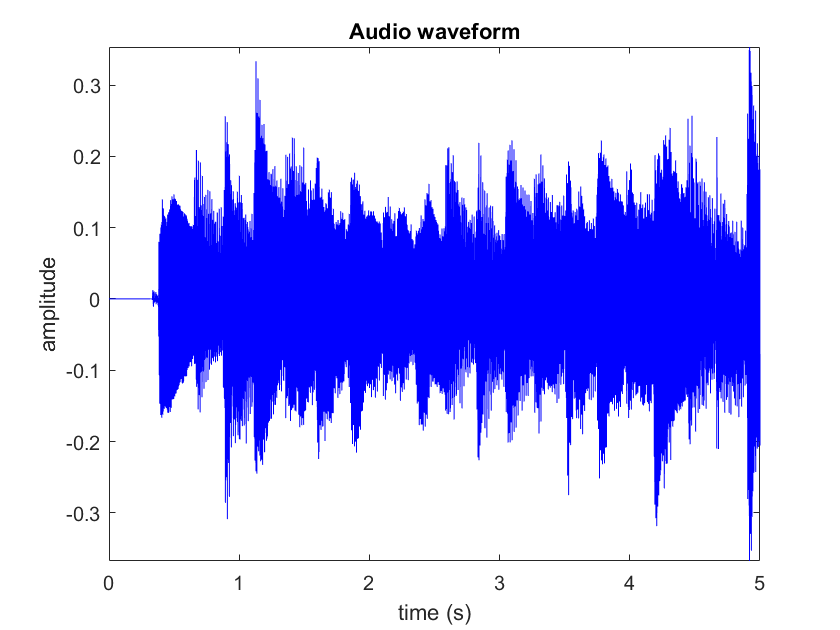

Its content is displayed in Figure 11.
 


bach = miraudio('bach_prelude.mp3','Extract',0,5,'s')

mirplay(bach);

Computing mirplay related to bach_prelude.mp3...
Playing file: bach_prelude.mp3


#### help with miraudio

Don't forget to ask Matlab for help if you don't remember how a function works!

help miraudio

    a = miraudio('filename') loads the sound file 'filename' (in WAV or AU
        format) into a miraudio object.
    a = miraudio('Folder') loads all the sound files in the CURRENT folder
        into a miraudio object.
    a = miraudio(v,sr), where v is a column vector, translates the vector v
        into a miraudio object. The sampling frequency is set to sr Hertz.
            Default value for sr: 44100 Hz.
    a = miraudio(b, ...), where b is already a miraudio object, performs 
        operations on b specified by the optional arguments (see below).
 
    Transformation options:
        miraudio(...,'Mono',0) does not perform the default summing of
            channels into one single mono track, but instead stores each 
            channel of the initial soundfile separately.       
        miraudio(...,'Center') centers the signals.
        miraudio(...,'Sampling',r) resamples at sampling rate r (in Hz).
            (Requires the Signal Processing Toolbox.)
        miraudio(.

### frequency-domain representations

#### Spectrum

Now let's calculate a spectrum for 'mus'.

Computing mirspectrum related to 7-3-17, 3_08 AM.m4a...
 
spec is the Spectrum related to 7-3-17, 3_08 AM.m4a, of sampling rate 48000 Hz.


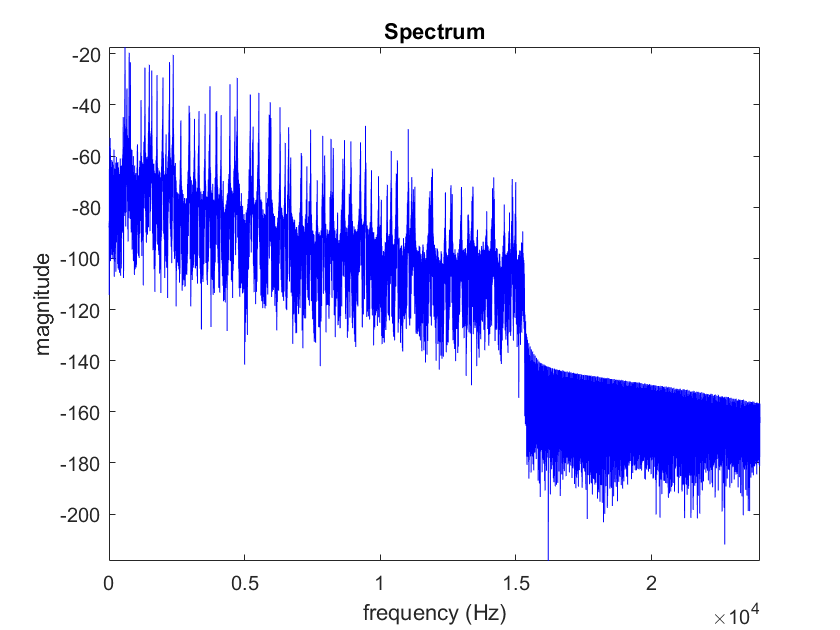

Its content is displayed in Figure 12.
 


spec = mirspectrum(mus,'Normal','dB')

And for the Bach example?

Computing mirspectrum related to bach_prelude.mp3...
 
bach_spec is the Spectrum related to bach_prelude.mp3, of sampling rate 44100 Hz.


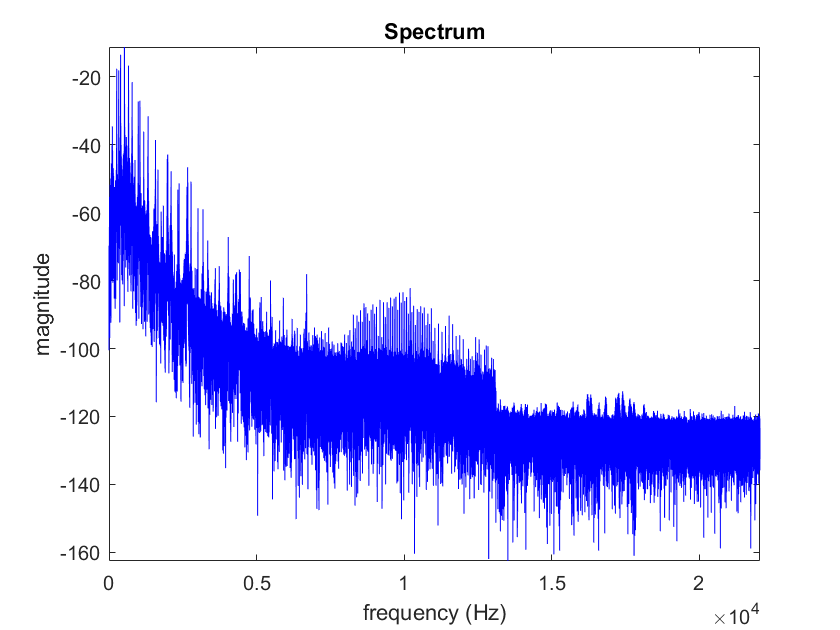

Its content is displayed in Figure 13.
 


bach_spec = mirspectrum(bach,'Normal','dB')

What if we only look at the energy within one octave? This is sometimes called a chromagram, and represents the amount of energy in the signal at each of 1200 cents within an octave, where 0 = C (100 cents = 1 semitone).

Computing mirspectrum related to bach_prelude.mp3...


Hint: if you specify a minimum value for the frequency range ('Min' option)
      and if you do not specify any frequency resolution ('Res' option), 
      the correct frequency resolution will be automatically chosen.
 
bach_spec is the Spectrum related to bach_prelude.mp3, of sampling rate 44100 Hz.


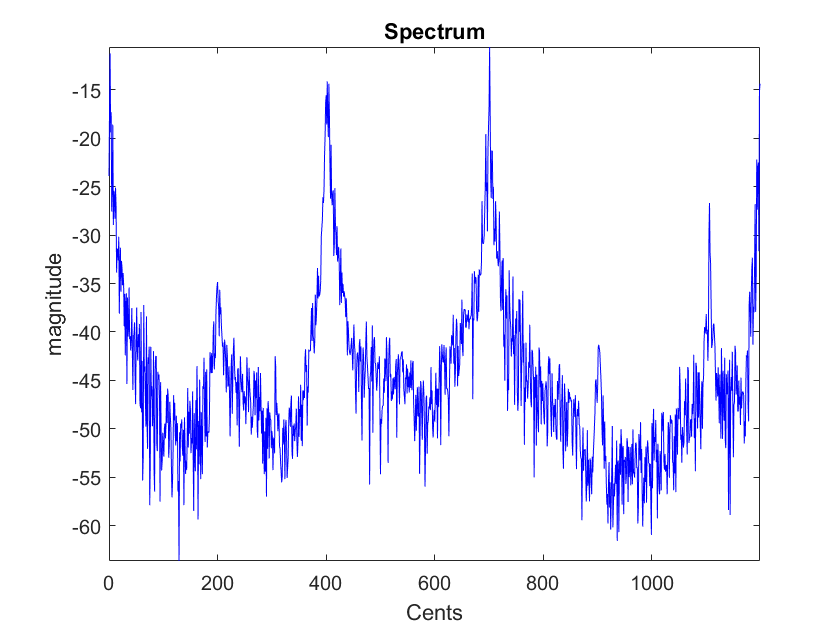

Its content is displayed in Figure 14.
 


bach_spec = mirspectrum(bach,'Normal','dB','Collapsed')

Notice the energy at 0, 400, and 700 cents. Those peaks represent C, E, and G, respectively. Not surprising given that this is the opening 5 s from Bach's prelude in C!

Let's smooth out that signal so it's easier to read.

Computing miraudio related to 7-3-17, 3_08 AM.m4a...
Computing mirsum related to 7-3-17, 3_08 AM.m4a...
Computing mirspectrum related to 7-3-17, 3_08 AM.m4a...


Hint: if you specify a minimum value for the frequency range ('Min' option)
      and if you do not specify any frequency resolution ('Res' option), 
      the correct frequency resolution will be automatically chosen.
Elapsed time is 0.999887 seconds.
 
concert_spec is the Spectrum related to 7-3-17, 3_08 AM.m4a, of sampling rate 48000 Hz.


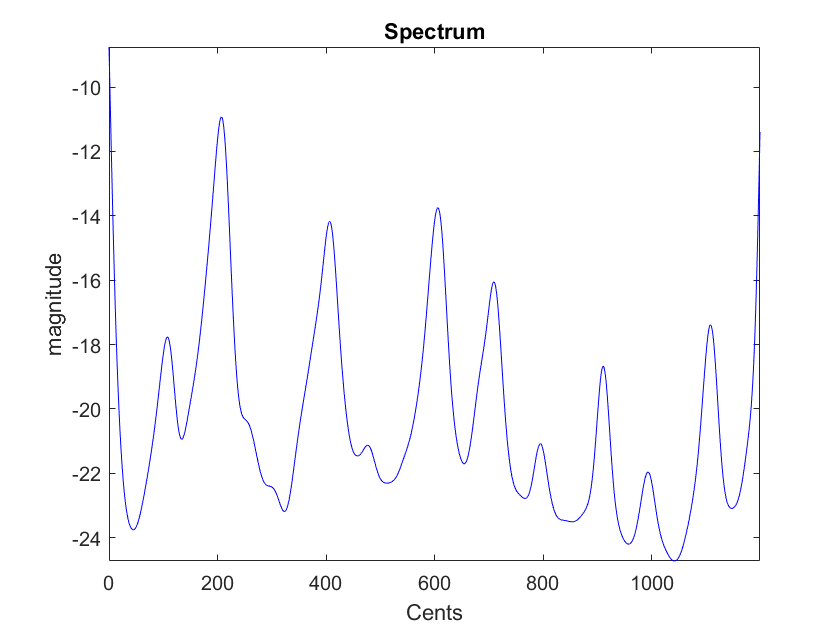

Its content is displayed in Figure 18.
 


concert_spec = mirspectrum('7-3-17, 3_08 AM.m4a','Normal','dB','Collapsed','Gauss')

#### spectrogram

Now let's take a look at a spectrum that changes over time, called a 'spectrogram'.

bach_spectrogram = mirspectrum(bach,'Normal','dB','Frame')

Computing mirspectrum related to bach_prelude.mp3...
 
bach_spectrogram is the Spectrum related to bach_prelude.mp3, of sampling rate 44100 Hz.
Its content is displayed in Figure 21.
 


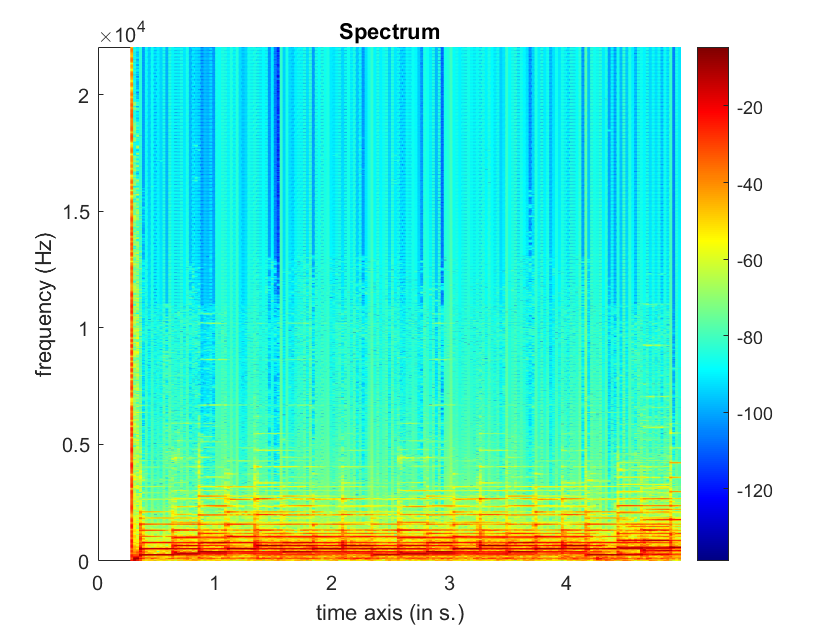

colormap(jet)
colorbar

## Feature Extraction

### dynamics

Now let's extract an intensity curve over time!

Chunk 1/3...
Computing miraudio related to bach_prelude.mp3...
Computing mirsum related to bach_prelude.mp3...
Computing mirrms related to bach_prelude.mp3...
Chunk 2/3...
Computing miraudio related to bach_prelude.mp3...
Computing mirsum related to bach_prelude.mp3...
Computing mirrms related to bach_prelude.mp3...
Chunk 3/3...
Computing miraudio related to bach_prelude.mp3...
Computing mirsum related to bach_prelude.mp3...
Computing mirrms related to bach_prelude.mp3...
Elapsed time is 4.297464 seconds.
 
The RMS energy related to file bach_prelude.mp3 is displayed in Figure 22.


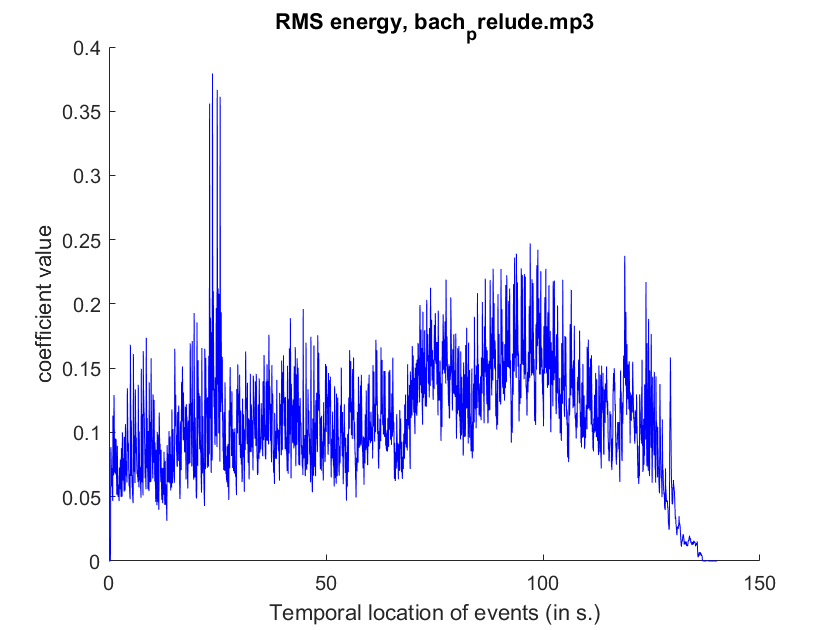

rms = mirrms('bach_prelude.mp3','Frame')

#### mirplayer

We can also follow the curve during real-time playback using mirplayer.

mirplayer(rms)

Chunk 1/2...
Computing miraudio related to bach_prelude.mp3...
Chunk 2/2...


Computing miraudio related to bach_prelude.mp3...
Computing mirsum related to bach_prelude.mp3...
Elapsed time is 3.694352 seconds.


### rhythm

#### mirtempo

How does the tempo of the performance change over time?

Chunk 1/2...
Computing miraudio related to bach_prelude.mp3...
Computing mirsum related to bach_prelude.mp3...
Computing mirfilterbank related to bach_prelude.mp3...
Computing mirenvelope related to bach_prelude.mp3...
Computing mironsets related to bach_prelude.mp3...
Computing mirenvelope related to bach_prelude.mp3...
Computing mirsum related to bach_prelude.mp3...
Chunk 2/2...


Computing miraudio related to bach_prelude.mp3...
Computing mirsum related to bach_prelude.mp3...
Computing mirfilterbank related to bach_prelude.mp3...
Computing mirenvelope related to bach_prelude.mp3...
Computing mironsets related to bach_prelude.mp3...
Computing mirenvelope related to bach_prelude.mp3...
Computing mirsum related to bach_prelude.mp3...
Computing mirenvelope related to bach_prelude.mp3...
Computing mirenvelope related to bach_prelude.mp3...
Computing mirautocor related to bach_prelude.mp3...
Computing mirpeaks related to bach_prelude.mp3...
Computing mirpeaks related to bach_prelude.mp3...
Computing mirsum related to bach_prelude.mp3...
Computing mirpeaks related to bach_prelude.mp3...
Computing mirtempo related to bach_prelude.mp3...
Elapsed time is 25.193729 seconds.
 
The Tempo related to file bach_prelude.mp3 is displayed in Figure 23.


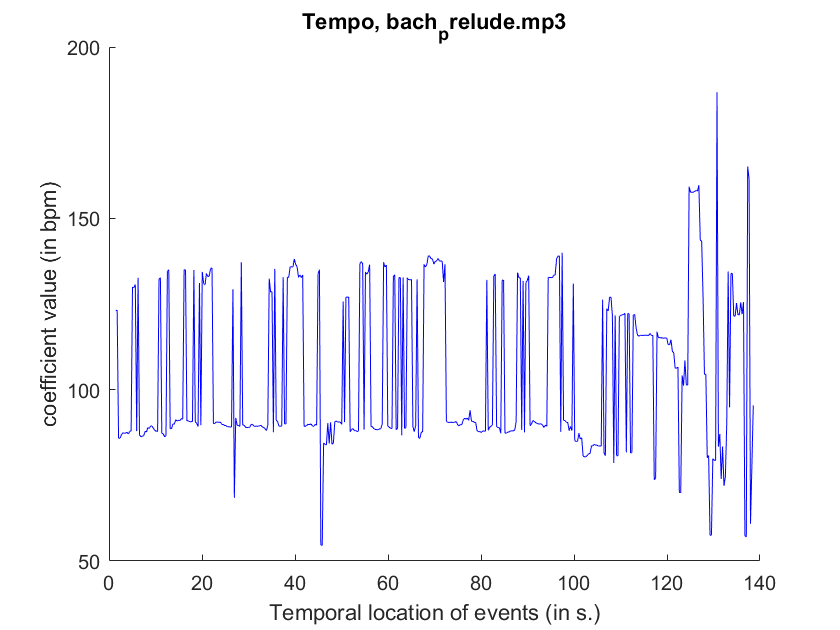

bpm = mirtempo('bach_prelude.mp3','Frame')

#### mirsegment

We can use mirsegment to identify segment boundaries in the music.

Computing miraudio related to Bean Growls.m4a...
Computing mirsum related to Bean Growls.m4a...
Elapsed time is 0.950751 seconds.
Computing mirspectrum related to Bean Growls.m4a...
Computing mirsimatrix related to Bean Growls.m4a...
Computing mirnovelty related to Bean Growls.m4a...
Computing convolution, please wait...
Computing mirpeaks related to Bean Growls.m4a...
 
seg is the Audio waveform related to Bean Growls.m4a, of sampling rate 44100 Hz.


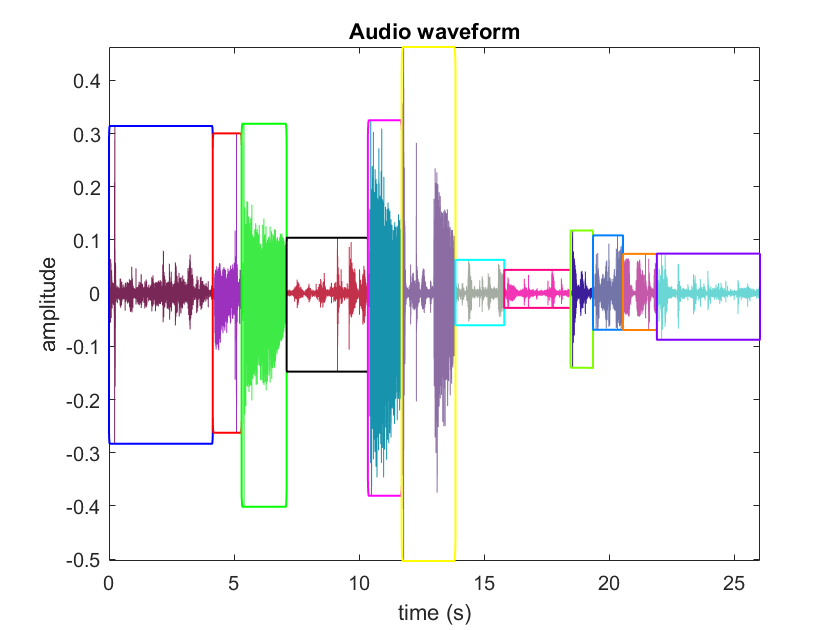

Its content is displayed in Figure 25.
 


seg = mirsegment('Bean Growls.m4a')

Let's check out the segment boundary analysis using mirplayer.

mirplayer(seg)

Computing miraudio related to Bean Growls.m4a...
Computing mirsum related to Bean Growls.m4a...
Elapsed time is 0.859117 seconds.


Computing mirfilterbank related to bach_prelude.mp3...
Computing mirautocor related to bach_prelude.mp3...
Computing mirsum related to bach_prelude.mp3...
Computing mirautocor related to bach_prelude.mp3...
Computing mirpeaks related to bach_prelude.mp3...
Computing mirpeaks related to bach_prelude.mp3...
Computing mirautocor related to bach_prelude.mp3...
Computing mirpitch related to bach_prelude.mp3...
Computing mirpeaks related to bach_prelude.mp3...
 
The Pitch related to file bach_prelude.mp3 is displayed in Figure 28.


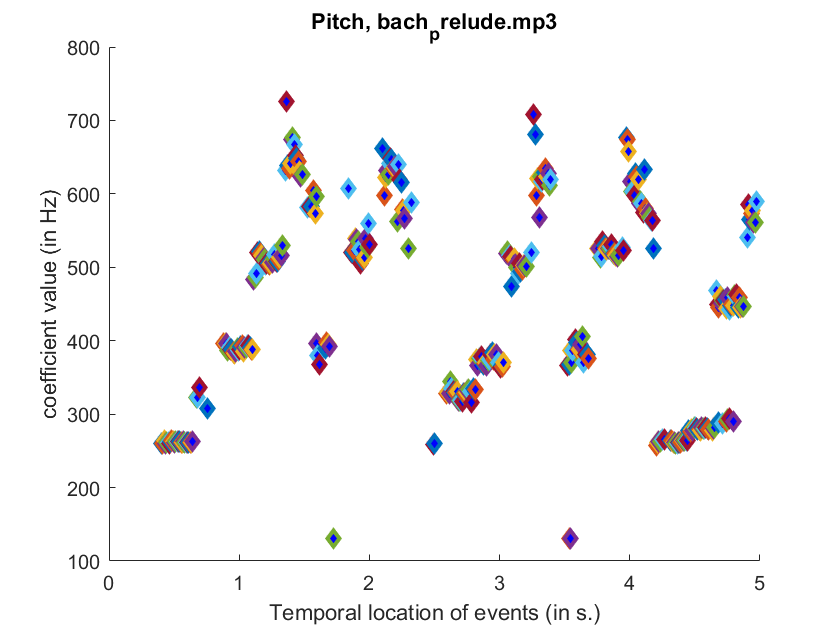

pitch = mirpitch(bach,'Frame')

mirplay(pitch)

Computing mirplay related to bach_prelude.mp3...
Playing Pitch related to file: bach_prelude.mp3

ans =

  0×0 empty cell array

